## Thermophysical Property Prediction

Empirical regression has limitations, especially when predictions are requested outside of the training region. Physics-based information can overcome this limitation by including fundamental engineering knowledge such as constraints during the training process. Constraints can be important physics-based information to improve machine learned predictions. Constraints are demonstrated on linear regression with sample data. The purpose of this [Thermophysical Property Case Study](https://apmonitor.com/pds/index.php/Main/ThermophysicalProperties) is to evaluate the performance of a neural network with and without constraints for thermophysical property predictions.

### Linear Regression with and without Constraints

Below is an example of linear regression with and without a lower bound constraint on a parameter. In this case, the constraint is on the slope (a≥0).

% Define Data
x = rand([1 100]) + linspace(0,100);
y = rand([1 100]) + linspace(0,1);
% Linear regression model
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   ________    __________    ______    __________

    (Intercept)     0.43989      0.053606    8.2059    9.2067e-13
    x1             0.011664    0.00091893    12.693    2.0694e-22


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 0.268
R-squared: 0.622,  Adjusted R-Squared: 0.618
F-statistic vs. constant model: 161, p-value = 2.07e-22

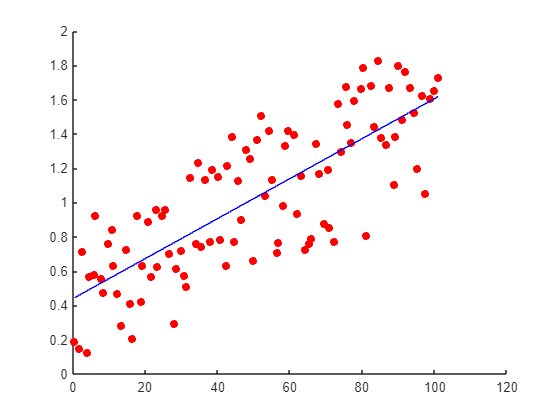

%There is a function that can do the next two lines of code. It is the After performing a linear regression using the Fit LM predict function as seen below
%coeffs = model.Coefficients.Estimate; % get coefficients
%y_predicted = coeffs(1) + coeffs(2)*x; % Calculate the corresponding y-values using the coefficients
y_predicted = predict(model, x')';

% Is it possible to make a constraint to the slope???

% Plot results
scatter(x,y,'r','filled')
hold on
plot(x,y_predicted, 'b')
hold off

### Predict Thermophysical Properties

**Background**: Parachor values are a factor in the prediction of several thermophysical properties such as surface tension and thermal conductivity. The parachor value (P) is used to predict surface tension with the difference between the density of saturated liquid ρL and saturated vapor ρV at the temperature of interest.

σ=(P(ρL−ρV))4

Surface tension and thermal conductivity are two specific properties that need improved predictions. A more accurate predictor of the parachor value (P) is an important step to improve those thermophysical properties. Most deep learning methods use a limited set of activation functions (ReLU, sigmoid, tanh, and linear) and perform unconstrained regression to minimize a loss function. The purpose of this case study is to explore the addition of physics-based information in the fitting process. This may include the use of new types of activation functions or constraints on the adjustable weights. The data for this case study is from Gharagheizi, et. al. (2011) who explored deep learning (a multi-layered neural network) to improve parachor predictions for 277 compounds from 40 functional groups.

- Name: The common chemical name

- Formula: Chemical formula of the compound

- CASN: Chemical Abstracts Service Registry Number

- Family: Chemical family of the compound

- Parachor: Estimate of parachor value

- Grp1-Grp40: Number of functional groups in the compound

**Objective**: Develop a prediction of the parachar from the chemical compound data set. Report the correlation coefficient (R2) for predicting Parachor in the test set. Randomly select values that split the data into a train (80%) and test (20%) set. Use Linear Regression and Neural Network (Deep Learning) with constraints. The solutions for regression without constraints or feature engineering are provided in this notebook. For the constrained cases, enforce a positive parachor contribution for each group. Discuss the performance of each on the train and test sets. Submit source code and a summary memo (max 2 pages) of your results.

#### Load Data

[Chemical Compound Data Set](http://apmonitor.com/pds/uploads/Main/thermo.txt)

url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt'

url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt'

#### Linear Regression without Constraints

data = readtable(url, 'VariableNamingRule', 'preserve')

Error using readtable
File not found at 'http://apmonitor.com/pds/uploads/Main/thermo.txt'.

Caused by:
    Error using websave
    The connection to URL 'http://apmonitor.com/pds/uploads/Main/thermo.txt' timed out after 5.000 seconds. The reason is
    "Connection timeout after 5100 ms". Perhaps the server is not responding or weboptions.Timeout needs to be set to a
    higher value.

functional_group_data = data(:, 6:45); % Isolate functional group data
data_train = table2array(functional_group_data(1:205, :)); % Split functional group data into a training set
data_validate = table2array(functional_group_data(206:end, :)); % Split functional group data into a validation set
p_train = table2array(data(1:205, 5)); % Split the parachor values into a training set 
p_validate = table2array(data(206:end, 5)); % Split the parachor values into a validation set 

% Perform linar regression
model = fitlm(data_train,p_train);

% Predict parachor values
p_predicted_train = predict(model, data_train);
p_predicted_validate = predict(model, data_validate);

% Graph
loglog(p_train, p_predicted_train, '.', p_validate, p_predicted_validate, '.');
xlabel('Measured');
ylabel('Predicted');
legend('Train', 'Validate', 'Location', 'northwest');

### Neural Network (Deep Learning) without Constraints

% Load your data
url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt';
data = readtable(url, 'VariableNamingRule', 'preserve');
functional_group_data = data(:, 6:45); % Isolate functional group data
data_train = functional_group_data(1:205, :); % Split functional group data into a training set
data_validate = functional_group_data(206:end, :); % Split functional group data into a validation set
p_train = data(1:205, 5); % Split the parachor values into a training set 
p_validate = data(206:end, 5); % Split the parachor values into a validation set 


% Create a neural network with 2 hidden layers of 10 neurons each
% net = feedforwardnet([10 10]);

% Set the activation function for the hidden layers and the output layer
% net.layers{1}.transferFcn = 'tansig';
% net.layers{2}.transferFcn = 'tansig';
% net.layers{3}.transferFcn = 'purelin';

layer = functionLayer(@(X) x)

layers = [
    sequenceInputLayer(1,"Name","sequence")
    layer
    tanhLayer("Name","tanh")
    layer
    layer
    regressionLayer("Name","regressionoutput")];



% Set the training algorithm and the maximum number of epochs
% net.trainFcn = 'trainlm';
% net.trainParam.epochs = 1000;
options = trainingOptions("adam", ...
    MaxEpochs=5000, ...
    Verbose=false, ...
    Plots="training-progress");
% Train the neural network
net = trainNetwork(data_train,p_train,layers, options);

% Simulate the neural network on test data
outputs = sim(net,data_validate);

% Evaluate the neural network
mse = mean((p_validate - outputs).^2)

### Neural Network (Deep Learning) without Constraints in Gekko

I don't know if this secion is possible...